clc;
clear;

pose = Pose2d.from_xydeg(0,0,0);
twist = Twist2d(.1,0,deg2rad(10));

backlog = [pose.translation.val_x pose.translation.val_y pose.rotation.value_radians];
for i=1:36
    pose = pose.pose_exp(twist);
    backlog = [backlog ; pose.translation.val_x pose.translation.val_y pose.rotation.value_radians];
end

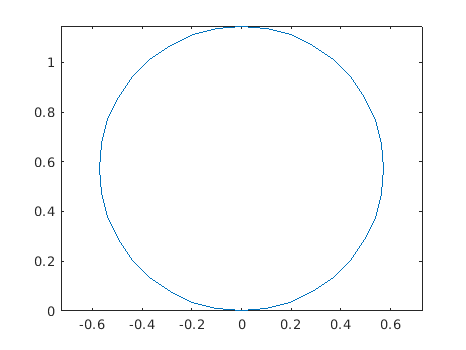

plot(backlog(:,1),backlog(:,2));
axis equal;